clc, clear, close all
datetime('now')

ans = datetime
   08-Jun-2023 19:31:31



addpath('C:\Users\emill\Desktop\IORN\L07');
load('constance.mat', 'hbar', 'm0', 'J2eV', 'eV2J');

L = 400 * 1e-10;
N = 1000;
dx = L / (N + 1);

Потенциальный порог

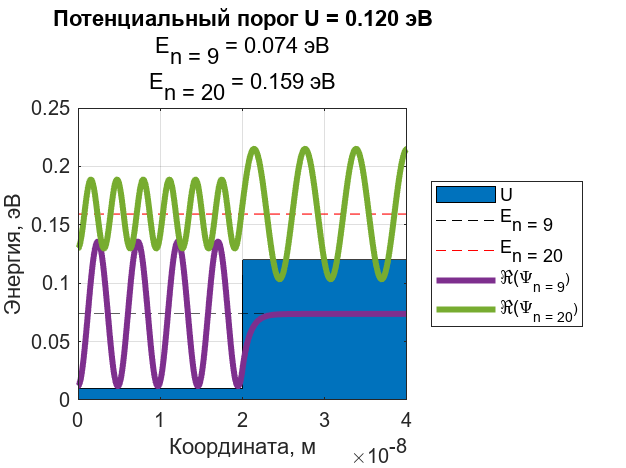

potential = 0.12;
U = ones(1, N) * potential * eV2J;
U(1, 1 : 500) = 0.01 * eV2J;

x = linspace(0, L, N);
t = hbar ^ 2 / (dx ^ 2 * 2 * m0);
v_1 = 2 * t * ones(1, N);
v_2 = -t * ones(1, N - 1);
H_1 = diag(v_1) + diag(v_2, 1) + diag(v_2, -1);

H_1_1 = H_1;
H_1_2 = H_1;

H_1_1(1, 1) = t;

H_1_2(1, 1) = t;
H_1_2(N, N) = t;

H_2 = diag(U);

H_l_e = H_1_1 + H_2;
H_h_e = H_1_2 + H_2;
 
[V_l_e, D_l_e] = eig(H_l_e);
[V_h_e, D_h_e] = eig(H_h_e);
m_1 = 9;
m_2 = 20;

psi_1 = V_l_e(:, m_1)';
psi_2 = V_h_e(:, m_2)';

figure(1);

area(x, U * J2eV);
hold on;
plot(x, D_l_e(m_1, m_1) * ones(1, N) * J2eV, 'LineStyle', '--', 'Color', 'k');
plot(x, D_h_e(m_2, m_2) * ones(1, N) * J2eV, 'LineStyle', '--', 'Color', 'r');
plot(x, psi_1 + D_l_e(m_1, m_1) * ones(1, N) * J2eV, 'LineWidth', 3);
plot(x, psi_2 + D_h_e(m_2, m_2) * ones(1, N) * J2eV, 'LineWidth', 3);

xlabel("Координата, м");
ylabel("Энергия, эВ");
title(sprintf('Потенциальный порог U = %.3f эВ', potential));
subtitle(sprintf("E_{n = %i} = %.3f эВ\n" + ...
"E_{n = %i} = %.3f эВ", m_1, D_l_e(m_1, m_1) * J2eV, m_2, D_h_e(m_2, m_2) * J2eV));
grid on;
xlim([0, L]);
legend('U', 'E_{n = 9}', 'E_{n = 20}', '\Re{(\Psi_{n = 9})}', '\Re{(\Psi_{n = 20})}', ...
'Location', 'eastoutside');

hold off;

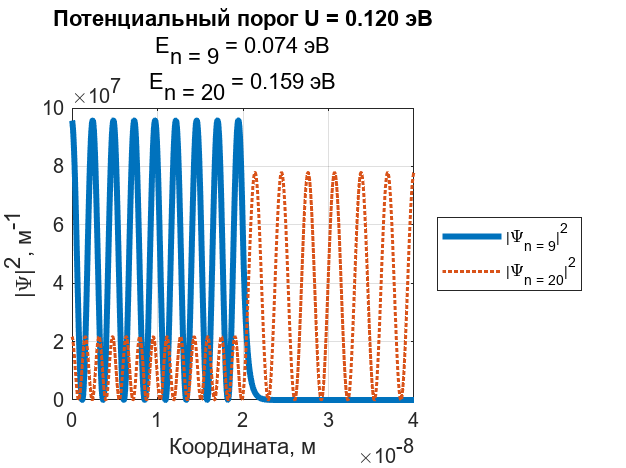


%Нормировка
psi_1 = psi_1 / sqrt(dx);
psi_2 = psi_2 / sqrt(dx);

figure(2);

plot(x, psi_1 .^ 2, 'LineWidth', 3);
hold on;
plot(x, psi_2 .^ 2, 'LineWidth', 1.5, 'LineStyle', ':');

xlabel("Координата, м");
ylabel("|\Psi|^2, м^{-1}");
title(sprintf('Потенциальный порог U = %.3f эВ', potential));
subtitle(sprintf("E_{n = %i} = %.3f эВ\n" + ...
"E_{n = %i} = %.3f эВ", m_1, D_l_e(m_1, m_1) * J2eV, m_2, D_h_e(m_2, m_2) * J2eV));
grid on;
xlim([0, L]);
legend('|\Psi_{n = 9}|^2', '|\Psi_{n = 20}|^2', 'Location', 'eastoutside');

hold off;

Барьер

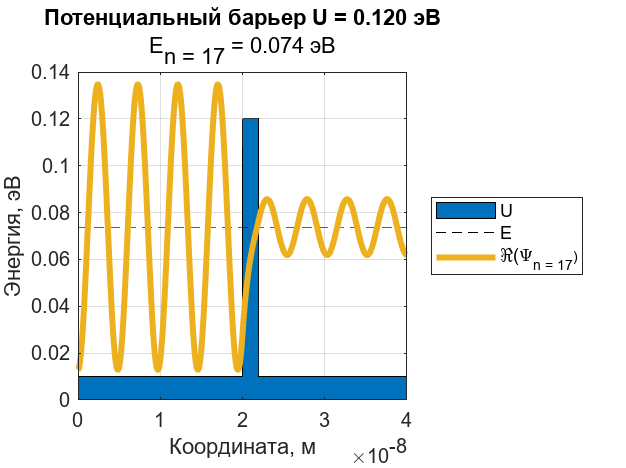

figure(3);

U(1, 550 : N) = 0.01 * eV2J;
H_2 = diag(U);

H = H_1_2 + H_2;
[V, D] = eig(H);

m = 17;
psi = V(:, m)';
area(x, U * J2eV);
hold on;
plot(x, D(m, m) * ones(1, N) * J2eV, 'LineStyle', '--', 'Color', 'k');
plot(x, psi + D(m, m) * ones(1, N) * J2eV, 'LineWidth', 3);

xlabel("Координата, м");
ylabel("Энергия, эВ");
title(sprintf('Потенциальный барьер U = %.3f эВ', potential));
subtitle(sprintf("E_{n = %i} = %.3f эВ", m, D(m, m) * J2eV));
grid on;
xlim([0, L]);
legend('U', 'E', '\Re{(\Psi_{n = 17})}', 'Location', 'eastoutside');

hold off;

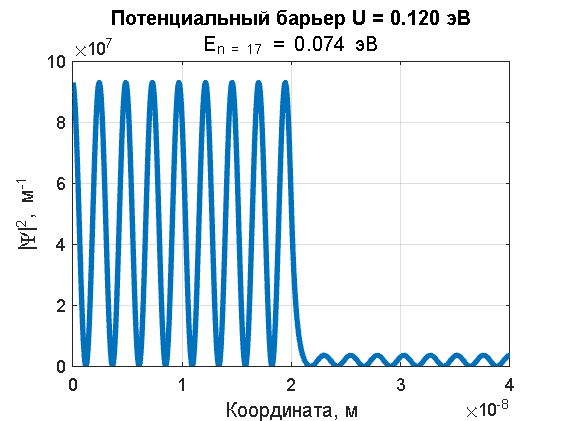


%Нормировка
psi = psi / sqrt(dx);

figure(4);

plot(x, psi .^ 2, 'LineWidth', 3);
xlabel("Координата, м");
ylabel("|\Psi|^2, м^{-1}");
title(sprintf('Потенциальный барьер U = %.3f эВ', potential));
subtitle(sprintf("E_{n = %i} = %.3f эВ", m, D(m, m) * J2eV));
grid on;

hold off;

Яма конечной глубины

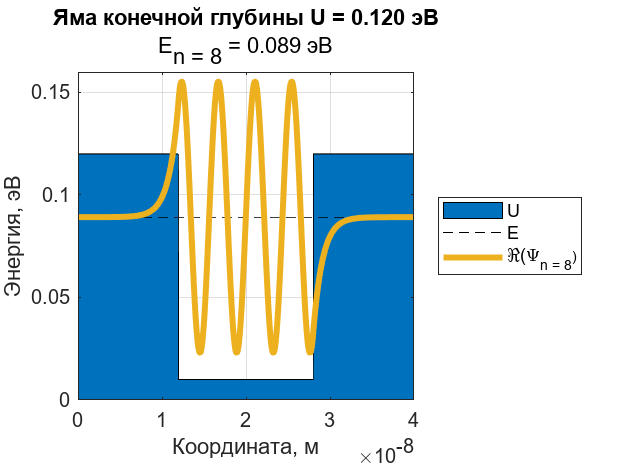

figure(5);

U(1, 1 : N) = potential * eV2J;
U(1, 300 : 700) = 0.01 * eV2J;

H_2 = diag(U);
H = H_1 + H_2;
[V, D] = eig(H);

m = 8;
psi = V(:, m)';

area(x, U * J2eV);
hold on;
plot(x, D(m, m) * ones(1, N) * J2eV, 'LineStyle', '--', 'Color', 'k');
plot(x, psi + D(m, m) * ones(1, N) * J2eV, 'LineWidth', 3);
xlabel("Координата, м");
ylabel("Энергия, эВ");
title(sprintf('Яма конечной глубины U = %.3f эВ', potential));
subtitle(sprintf("E_{n = %i} = %.3f эВ", m, D(m, m) * J2eV));
grid on;
xlim([0, L]);
legend('U', 'E', '\Re{(\Psi_{n = 8})}', 'Location', 'eastoutside');

hold off;

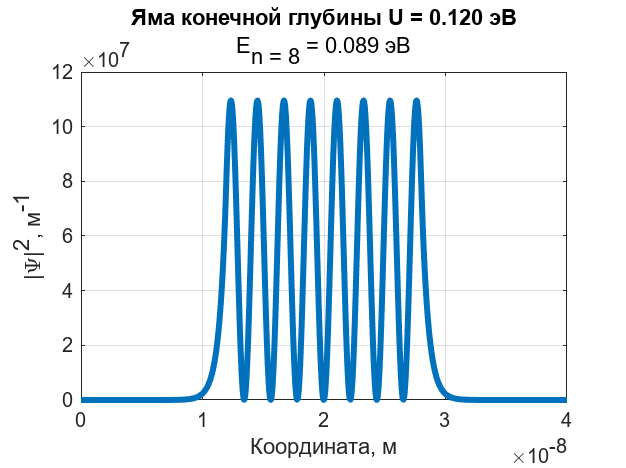


%Нормировка
psi = psi / sqrt(dx);

figure(6);

plot(x, psi .^ 2, 'LineWidth', 3);

xlabel("Координата, м");
ylabel("|\Psi|^2, м^{-1}");
title(sprintf('Яма конечной глубины U = %.3f эВ', potential));
subtitle(sprintf("E_{n = %i} = %.3f эВ", m, D(m, m) * J2eV));
grid on;
xlim([0, L]);